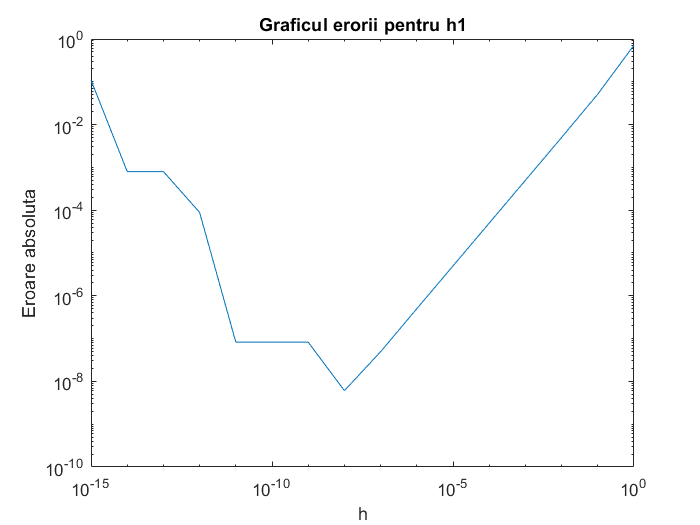

h1 = 10.^(-15:0);
approx1 = (exp(h1) - 1) ./ h1;
error1 = abs(approx1 - 1);

clf;
loglog(h1, error1);
xlabel('h');
ylabel('Eroare absoluta');
title('Graficul erorii pentru h1');

[min_err1, id_h1] = min(error1);
min_err1, h1(id_h1), sqrt(eps)

min_err1 = 6.0775e-09

ans = 1.0000e-08

ans = 1.4901e-08

Eroarea minima este de ordinul e-9, iar valoarea optima a lui h este in jur de sqrt(eps).

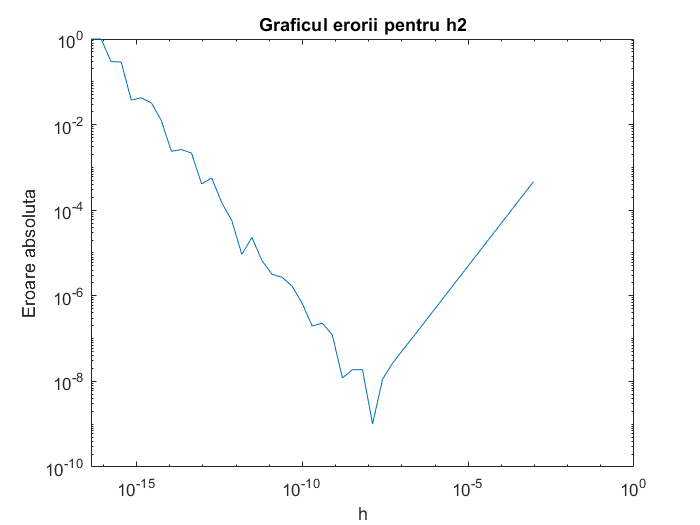

k = 10:54;
h2 = 2.01.^(-k);
approx2 = (exp(h2) - 1) ./ h2;
error2 = abs(approx2 - 1);

clf;
loglog(h2, error2);
xlabel('h');
ylabel('Eroare absoluta');
title('Graficul erorii pentru h2');

[min_err2, id_h2] = min(error2);
min_err2, h2(id_h2), sqrt(eps)

min_err2 = 1.0176e-09

ans = 1.3089e-08

ans = 1.4901e-08

De asemenea se observa ca eroarea minima este de ordinul e-9, iar valoarea optima a lui h este in jur de sqrt(eps).

O incercare pentru a obtine o aproximare mai buna este sa folosim aproximarea cu seria Taylor.

syms hs;
f_sym = exp(hs) - 1;
taylor_series = taylor(f_sym, hs, 'Order', 6)

$$taylor\_series = \frac{{\mathrm{hs}}^{5}}{120}+\frac{{\mathrm{hs}}^{4}}{24}+\frac{{\mathrm{hs}}^{3}}{6}+\frac{{\mathrm{hs}}^{2}}{2}+\mathrm{hs}$$

f = @taylor_approx; % Apare la final

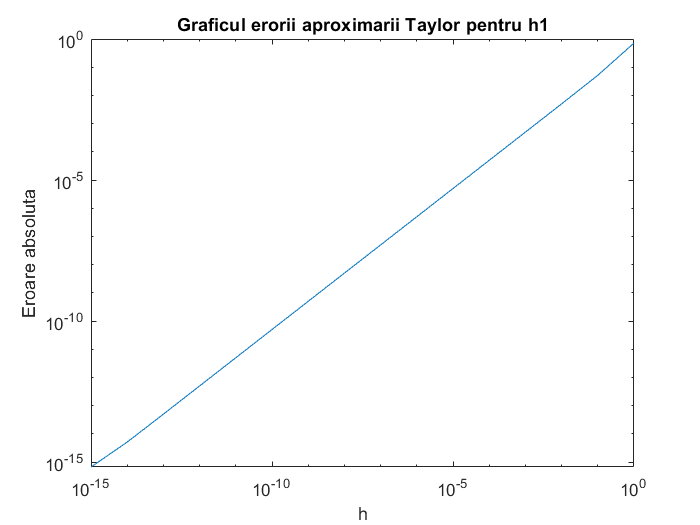

approx1_taylor = arrayfun(f, h1) ./ h1;
error1_taylor = abs(approx1_taylor - 1);

clf;
loglog(h1, error1_taylor);
xlabel('h');
ylabel('Eroare absoluta');
title('Graficul erorii aproximarii Taylor pentru h1');

[min_err1_taylor, id_h1] = min(error1_taylor);
min_err1_taylor, h1(id_h1)

min_err1_taylor = 6.6613e-16

ans = 1.0000e-15

Se obtine o eroare mai mica, deci o aproximare mai buna in jurul lui x=0.

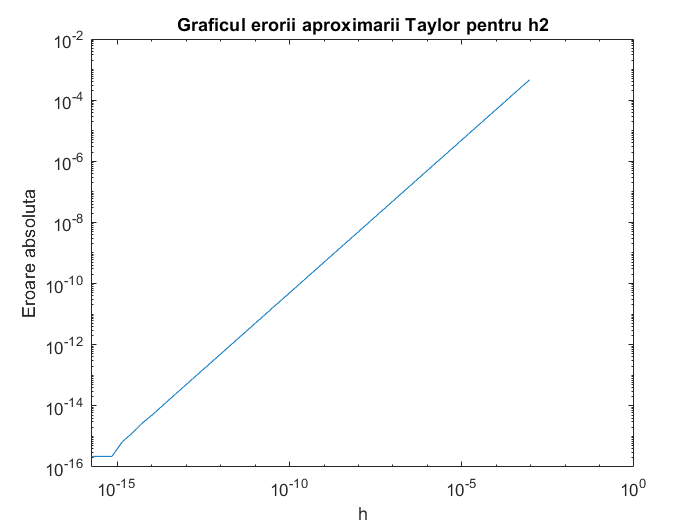

approx2_taylor = arrayfun(f, h2) ./ h2;
error2_taylor = abs(approx2_taylor - 1);

clf;
loglog(h2, error2_taylor);
xlabel('h');
ylabel('Eroare absoluta');
title('Graficul erorii aproximarii Taylor pentru h2');

[min_err2_taylor, id_h2] = min(error2_taylor);
min_err2_taylor, h2(id_h2)

min_err2_taylor = 0

ans = 8.5233e-17

De asemenea, se obtine o eroare mai mica, deci o aproximare mai buna in jurul lui x=0.

Alta posibil remediu ar fi sa folosim formula aproximarii cu diferenta centrala.


$$\frac{f\left(x+h\right)-f\left(x-h\right)}{2h}$$


dfc = @(h) (exp(h) - exp(-h)) / (2*h)

dfc = function_handle with value:
    @(h)(exp(h)-exp(-h))/(2*h)


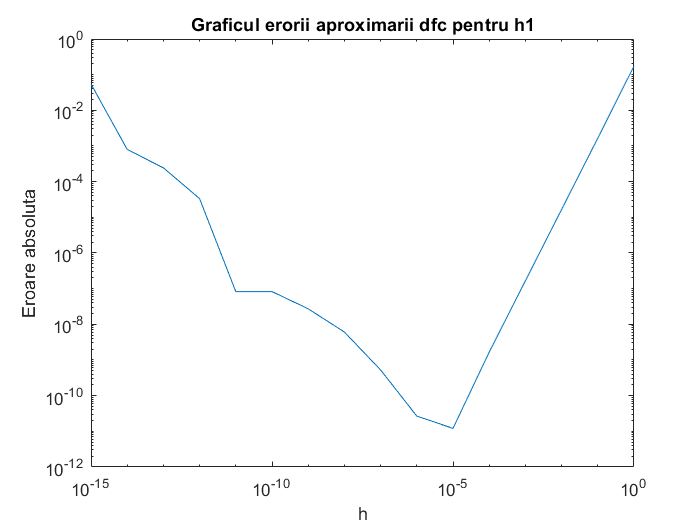

approx1_dfc = arrayfun(dfc, h1);
error1_dfc = abs(approx1_dfc - 1);

clf;
loglog(h1, error1_dfc);
xlabel('h');
ylabel('Eroare absoluta');
title('Graficul erorii aproximarii dfc pentru h1');

[min_err1_dfc, id_h1] = min(error1_dfc);
min_err1_dfc, h1(id_h1)

min_err1_dfc = 1.2102e-11

ans = 1.0000e-05

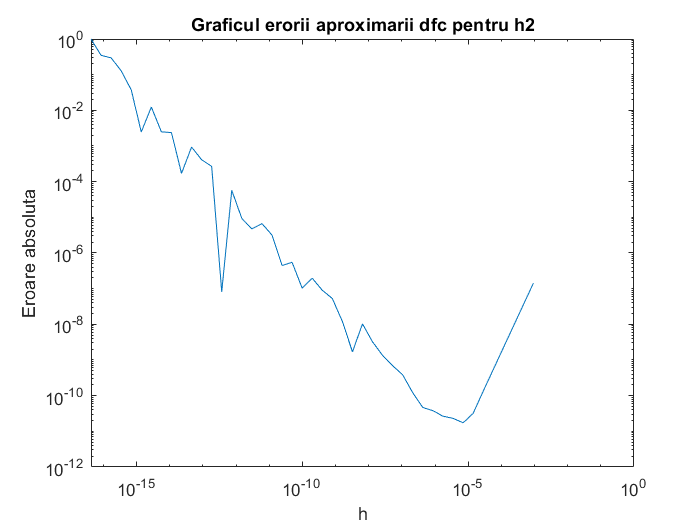

approx2_dfc = arrayfun(dfc, h2);
error2_dfc = abs(approx2_dfc - 1);

clf;
loglog(h2, error2_dfc);
xlabel('h');
ylabel('Eroare absoluta');
title('Graficul erorii aproximarii dfc pentru h2');

[min_err2_dfc, id_h2] = min(error2_dfc);
min_err2_dfc, h2(id_h2)

min_err2_dfc = 1.7343e-11

ans = 7.0092e-06

Prin aceasta metoda se obtine o aproximare mai buna.

function y=taylor_approx(x) % pentru e^x - 1
    order = 16;
    t = x;
    y = 0;
    for i = 1:order
       y = y + t;
       t = t * x / (i + 1);
    end
end